## definition of constants

clear;
clc;

Jex=0.63;
Jey=0.69;
Jez=0.86;
Jlx=0.53;
Jly=0.15;
Jlz=0.4;
Jax=3.07;
Jay=4.13;
Jaz=2.61;
Rm=1.22;
Lm=5.13;
Km=0.363;
Kt=0.31;
n=50; %this is n_e from the paper
%n_a=150; not being used rn
beta=deg2rad(35);
max_time=400;
v1_desired=0.5;
v2_desired=0.5;
v3_desired=0.5;

global time_prior ...
        integral_v1_dot integral_v2_dot integral_v3_dot ...
        error_v1_dot_prior error_v2_dot_prior error_v3_dot_prior ...
        integral_v1 integral_v2 integral_v3 ...
        error_v1_prior error_v2_prior error_v3_prior;
time_prior = 0; 
integral_v1_dot = 0;
integral_v2_dot = 0;
integral_v3_dot = 0;
error_v1_dot_prior = 0;
error_v2_dot_prior = 0;
error_v3_dot_prior = 0;  
integral_v1 = 0;
integral_v2 = 0;
integral_v3 = 0;
error_v1_prior = 0;
error_v2_prior = 0;
error_v3_prior = 0; 

## ode45 and plotting

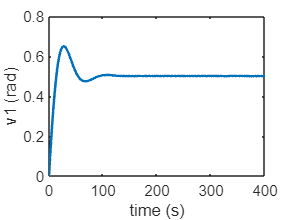

%tspan=0:dt:max_time;
tspan=[0 max_time];
x_init=transpose([0 0 0 0 0 0 0 0 0]);
%opts = odeset('RelTol',1e-6,'AbsTol',1e-7);
%x=ode4(@(x) odefcn(x), 0, dt, max_time, x_init);
[t, x]=ode45(@(t, x) odefcn(t, x), tspan, x_init);

y_v1=x(:, 1);
y_v2=x(:, 4);
y_v3=x(:, 7);

%plot(linspace(0, 20, length(t)), t);

y_v1_dot=x(:, 2);
y_v2_dot=x(:, 5);
y_v3_dot=x(:, 8);

graph_v1=plot(t, y_v1);
xlabel('time (s)');
ylabel('v1 (rad)');
set(graph_v1, 'linewidth', 1.5);

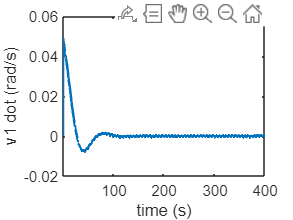


graph_v1_dot=plot(t, y_v1_dot);
xlabel('time (s)');
ylabel('v1 dot (rad/s)');
set(graph_v1_dot, 'linewidth', 1.5);

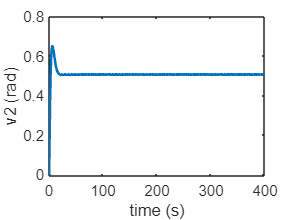


graph_v2=plot(t, y_v2);
xlabel('time (s)');
ylabel('v2 (rad)');
set(graph_v2, 'linewidth', 1.5);

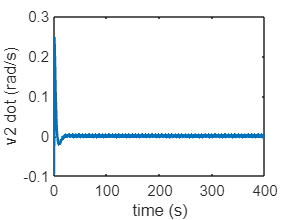


graph_v2_dot=plot(t, y_v2_dot);
xlabel('time (s)');
ylabel('v2 dot (rad/s)');
set(graph_v2_dot, 'linewidth', 1.5);

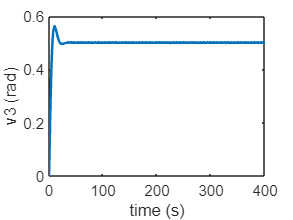


graph_v3=plot(t, y_v3);
xlabel('time (s)');
ylabel('v3 (rad)');
set(graph_v3, 'linewidth', 1.5);

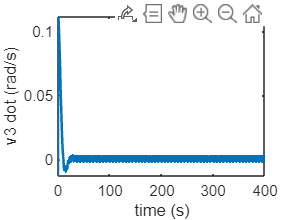


graph_v3_dot=plot(t, y_v3_dot);
xlabel('time (s)');
ylabel('v3 dot (rad/s)');
set(graph_v3_dot, 'linewidth', 1.5);

## function definitions

function dxdt = odefcn(t, x)
    Jex=0.63;
    Jey=0.69;
    Jez=0.86;
    Jlx=0.53;
    Jly=0.15;
    Jlz=0.4;
    Jax=3.07;
    Jay=4.13;
    Jaz=2.61;
    Rm=1.22;
    Lm=5.13;
    Km=0.363;
    Kt=0.31;
    n=50; %this is n_e from the paper
    %n_a=150; not being used rn
    beta=deg2rad(35);
    v1_desired=0.5;
    v2_desired=0.5;
    v3_desired=0.5;
    dxdt=zeros(9, 1);
    global time_prior ...
           error_v1_dot_prior error_v2_dot_prior error_v3_dot_prior ...
           error_v1_prior error_v2_prior error_v3_prior;

    %state space definition
    %azimuth axis
    v1=x(1, 1); %angular displacement
    v1_dot=x(2, 1); %angular velocity
    ia=x(3, 1); %currrent
    %xlevel axis
    v2=x(4, 1); %angular displacement
    v2_dot=x(5, 1); %angular velocity
    il=x(6, 1); %currrent
    %elevation axis
    v3=x(7, 1); %angular displacement
    v3_dot=x(8, 1); %angular velocity
    ie=x(9, 1); %currrent

    %definition of motor torques
    Mey=n*Kt*ie;
    Mlz=n*Kt*il;
    Maz=n*Kt*ia;

    %definition of total inertias
    JLz=Jlz+(cos(v3)^2)*Jex+(sin(v3)^2)*Jez;
    JAz=Jaz+(cos(v2)^2)*(cos(beta)^2)*(Jlx+(sin(v3)^2)*Jex+(cos(v3)^2)*Jez) ...
         +2*cos(v2)*sin(v3)*cos(v3)*sin(beta)*cos(beta)*(Jex-Jez) ...
         +(sin(v2)^2)*(cos(beta)^2)*(Jly+Jey) ...
         +(sin(beta)^2)*(Jlz+(cos(v3)^2)*Jex+(sin(v3)^2)*Jez);

    phi=sin(t);
    psi=sin(t);
    tht=sin(t);

    phi_dot=cos(t);
    psi_dot=cos(t);
    tht_dot=cos(t);

    phi_ddot=-sin(t);
    psi_ddot=-sin(t);
    tht_ddot=-sin(t);

    Tab=[cos(v1) sin(v1) 0; -sin(v1) cos(v1) 0; 0 0 1];
    Tla=[sin(beta)*cos(v2) sin(v2) cos(beta)*cos(v2); -sin(beta)*sin(v2) cos(v2) -cos(beta)*sin(v2); -cos(beta) 0 sin(beta)];
    Tel=[-sin(v3) 0 -cos(v3); 0 1 0; cos(v3) 0 -sin(v3)];

    omegaB=[phi_dot-(psi_dot*sin(tht)); (tht_dot*cos(phi))+(psi_dot*cos(tht)*sin(phi)); (psi_dot*cos(tht)*cos(phi))-(tht_dot*sin(phi))];
    omegaA=Tab*omegaB+[0; 0; v1_dot];
    omegaL=Tla*omegaA+[0; 0; v2_dot];
    omegaE=Tel*omegaL+[0; v3_dot; 0];

    %for B frame
    %pB_dot=omegaB(1, 1);    
    %rB_dot=omegaB(2, 1);
    %qB_dot=omegaB(3, 1);

    %for A frame
    pA_dot=omegaA(1, 1);    
    rA_dot=omegaA(2, 1);
    qA_dot=omegaA(3, 1);

    %for L frame
    pL_dot=omegaL(1, 1);    
    rL_dot=omegaL(2, 1);
    qL_dot=omegaL(3, 1);

    %for E frame
    pE_dot=omegaE(1, 1);    
    rE_dot=omegaE(2, 1);
    qE_dot=omegaE(3, 1);

    %disturbance torques
    Mde=pE_dot*rE_dot*(Jey-Jez);

    Mdl=(rE_dot*v3_dot+rE_dot*qL_dot)*cos(v3)*Jez+pL_dot*qL_dot*(Jlx-Jly) ...
         -(pE_dot*v3_dot+pE_dot*qL_dot)*sin(v3)*Jex-qE_dot*pL_dot*Jey;

    Mda=v2_dot*sin(v2)*cos(beta)*(pE_dot*sin(v3)*Jex-pL_dot*Jlx-rE_dot*cos(v3)*Jez) ...
         +v3_dot*cos(v2)*cos(beta)*(rE_dot*sin(v3)*Jez-pE_dot*cos(v3)*Jex) ...
         +v2_dot*cos(v2)*cos(beta)*(qL_dot*Jly+qE_dot*Jey) ...
         +v3_dot*sin(beta)*(cos(v3)*rE_dot*Jez-sin(v3)*pE_dot*Jex) ...
         +pA_dot*qA_dot*(Jax-Jay) ...
         +cos(beta)*qA_dot*(cos(v3)*pE_dot*Jex-rL_dot*Jlz+sin(v3)*rE_dot*Jez) ...
         -(cos(v2)*pA_dot+sin(v2)*sin(beta)*qA_dot)*(qL_dot*Jly+qE_dot*Jey) ...
         +(qA_dot*cos(v2)*sin(beta)-pA_dot*sin(v2))*(pL_dot*Jlx-pE_dot*sin(v3)*Jex+rE_dot*cos(v3)*Jez);

    %differential equations for ode45
    %azimuth axis
    dxdt(1, 1) = v1_dot;
    dxdt(2, 1) = (Maz+Mda)/JAz-cos(phi)*cos(tht)*psi_ddot ...
                  +sin(phi)*tht_ddot+cos(phi)*phi_dot*tht_dot ...
                  +cos(tht)*sin(phi)*phi_dot*psi_dot ...
                  +cos(phi)*sin(tht)*phi_dot*tht_dot; %v1_double_dot

    %control of azimuth joint
    error_v1=v1_desired-v1;
    error_dot_v1=-v1_dot;
    v1_dot_desired=control_v1(t, error_v1, time_prior, error_dot_v1);

    error_v1_dot=v1_dot_desired-v1_dot; %v1_dot is actual value
    error_dot_v1_dot=-dxdt(2, 1);
    Va=control_v1_dot(t, error_v1_dot, time_prior, error_dot_v1_dot); %voltage of azimuth axis
    
    %clipping of voltage
    Va=clip(Va, 10, -10);

    dxdt(3, 1)= (Va-Rm*ia-Km*n*v1_dot)/Lm; %ia_dot
    %x level axis
    dxdt(4, 1) = v2_dot;
    dxdt(5, 1) = -(0.819*cos(v1)*sin(tht)*psi_ddot+cos(tht)*psi_dot*tht_dot-phi_ddot ...
                 -0.574*sin(phi)*tht_ddot-0.819*sin(v1)*cos(phi)*tht_ddot ...
                 +cos(tht)*sin(phi)*psi_ddot-sin(phi)*phi_dot*tht_dot ...
                 +cos(phi)*cos(tht)*phi_dot*psi_dot-sin(phi)*sin(tht)*psi_dot*tht_dot ...
                 +0.574*cos(phi)*cos(tht)*psi_ddot-0.574*cos(phi)*phi_dot*tht_dot ...
                 +0.574*dxdt(2, 1)-0.819*sin(v1)*sin(tht)*psi_dot-phi_dot*v1_dot ...
                 -0.819*cos(v1)*cos(phi)*tht_dot+cos(tht)*sin(phi)*psi_dot*v1_dot ...
                 -0.574*cos(tht)*sin(phi)*phi_dot*psi_dot ...
                 -0.574*cos(phi)*sin(tht)*psi_dot*tht_dot-((Mlz+Mdl)/JLz)); %v2_double_dot

    %control of xlevel joint
    error_v2=v2_desired-v2;
    error_dot_v2=-v2_dot;
    v2_dot_desired=control_v2(t, error_v2, time_prior, error_dot_v2);

    error_v2_dot=v2_dot_desired-v2_dot; %v2_dot is actual value
    error_dot_v2_dot=-dxdt(5, 1);
    Vl=control_v2_dot(t, error_v2_dot, time_prior, error_dot_v2_dot); %voltage of xlevel axis
   
    %clipping of voltage
    Vl=clip(Vl, 10, -10);

    dxdt(6, 1) = (Vl-Rm*il-Km*n*v2_dot)/Lm; %il_dot
    %elevation axis
    dxdt(7, 1) = v3_dot;
    dxdt(8, 1) = -(cos(v2)*(sin(v1)*(sin(tht)*psi_ddot + cos(tht)*psi_dot*tht_dot ...
                    - phi_ddot) + cos(v1)*(cos(phi)*tht_ddot ...
                    + cos(tht)*sin(phi)*psi_ddot - sin(phi)*phi_dot*tht_dot ...
                    + cos(phi)*cos(tht)*phi_dot*psi_dot ...
                    - sin(phi)*sin(tht)*psi_dot*tht_dot) ...
                    - sin(v1)*(cos(phi)*tht_dot ...
                    + cos(tht)*sin(phi)*psi_dot)*v1_dot + cos(v1)*(sin(tht)*psi_dot ...
                    - phi_dot)*v1_dot) - 0.574*sin(v2)*(sin(v1)*(cos(phi)*tht_ddot ...
                    + cos(tht)*sin(phi)*psi_ddot - sin(phi)*phi_dot*tht_dot ...
                    + cos(phi)*cos(tht)*phi_dot*psi_dot ...
                    - sin(phi)*sin(tht)*psi_dot*tht_dot) ...
                    - cos(v1)*(sin(tht)*psi_ddot + cos(tht)*psi_dot*tht_dot ...
                    - phi_ddot) + sin(v1)*(sin(tht)*psi_dot ...
                    - phi_dot)*v1_dot + cos(v1)*(cos(phi)*tht_dot ...
                    + cos(tht)*sin(phi)*psi_dot)*v1_dot) ...
                    + 0.819*sin(v2)*(sin(phi)*tht_ddot ...
                    - cos(phi)*cos(tht)*psi_ddot + cos(phi)*phi_dot*tht_dot ...
                    - dxdt(2, 1) + cos(tht)*sin(phi)*phi_dot*psi_dot ...
                    + cos(phi)*sin(tht)*psi_dot*tht_dot) ...
                    - sin(v2)*(cos(v1)*(cos(phi)*tht_dot + cos(tht)*sin(phi)*psi_dot) ...
                    + sin(v1)*(sin(tht)*psi_dot - phi_dot))*v2_dot ...
                    - 0.574*cos(v2)*v2_dot*(sin(v1)*(cos(phi)*tht_dot ...
                    + cos(tht)*sin(phi)*psi_dot) - cos(v1)*(sin(tht)*psi_dot ...
                    - phi_dot)) -((Mey+Mde)/Jey) - 0.819*cos(v2)*v2_dot*(v1_dot ...
                    - sin(phi)*tht_dot + cos(phi)*cos(tht)*psi_dot)); %v3_double_dot
    %control of elevation joint
    error_v3=v3_desired-v3;
    error_dot_v3=-v3_dot;
    v3_dot_desired=control_v3(t, error_v3, time_prior, error_dot_v3);

    error_v3_dot=v3_dot_desired-v3_dot; %v3_dot is actual value
    error_dot_v3_dot=-dxdt(8, 1);
    Ve=control_v3_dot(t, error_v3_dot, time_prior, error_dot_v3_dot); %voltage of elevation axis
   
    %clipping of voltage
    Ve=clip(Ve, 10, -10);

    dxdt(9, 1) = (Ve-Rm*ie-Km*n*v3_dot)/Lm; %ie_dot

    error_v1_prior=error_v1;
    error_v1_dot_prior=error_v1_dot;
    error_v2_prior=error_v2;
    error_v2_dot_prior=error_v2_dot;
    error_v3_prior=error_v3;
    error_v3_dot_prior=error_v3_dot;
    time_prior=t;

end

function u = control_v1(t, error, time_prior, error_dot)
    %PID gains
    kp=35; %80.85
    ki=2; 
    kd=400; 
    %kd=kd*1000;
    bias=0; 
    
    global integral_v1;
    integral_v1=integral_v1+ki*error*(t-time_prior);
    u=kp*error+integral_v1+kd*error_dot+bias;
end

function u = control_v1_dot(t, error, time_prior, error_dot)
    %PID gains
    kp=5; 
    ki=0; 
    kd=6000; 
    %kd=kd*1000;
    bias=0; 
    
    global integral_v1;
    integral_v1=integral_v1+ki*error*(t-time_prior);
    u=kp*error+integral_v1+kd*error_dot+bias;
end

function u = control_v2(t, error, time_prior, error_dot)
    %PID gains
    kp=15;
    ki=2; 
    kd=70;
    %kd=kd*1000;
    bias=0; 
    
    global integral_v2;
    integral_v2=integral_v2+ki*error*(t-time_prior);
    u=kp*error+integral_v2+kd*error_dot+bias;
end

function u = control_v2_dot(t, error, time_prior, error_dot)
    %PID gains
    kp=15;
    ki=2; 
    kd=200;
    %kd=kd*1000;
    bias=0; 
    
    global integral_v2;
    integral_v2=integral_v2+ki*error*(t-time_prior);
    u=kp*error+integral_v2+kd*error_dot+bias;
end

function u = control_v3(t, error, time_prior, error_dot)
    %PID gains
    kp=10; 
    ki=2; 
    kd=60; 
    %kd=kd*1000;
    bias=0;
    
    global integral_v3;
    integral_v3=integral_v3+ki*error*(t-time_prior);
    u=kp*error+integral_v3+kd*error_dot+bias;
end

function u = control_v3_dot(t, error, time_prior, error_dot)
    %PID gains
    kp=10; 
    ki=2; 
    kd=60; 
    %kd=kd*1000;
    bias=0;
    
    global integral_v3;
    integral_v3=integral_v3+ki*error*(t-time_prior);
    u=kp*error+integral_v3+kd*error_dot+bias;
end


function val = clip(val, upper_bound, lower_bound)
   if val>upper_bound
        val=upper_bound;
    end
    if val<lower_bound
        val=lower_bound;
    end 
end



